# Parametros geograficos y fronteras paises

%% Geographical bounds (expanded Mediterranean region)
long_min_bound = -10;
long_max_bound = 45;
lat_min_bound = 27;
lat_max_bound = 50;
% Read the shapefile for country boundaries
% Read the shapefile for country boundaries

countries = readgeotable("C:\Users\pache\Documents\AAB--Practicas\IMEDEA\CODIGO - DATOS" + ...
    "\\ne_10m_admin_0_countries\ne_10m_admin_0_countries.shp");



# Carga de datos


load("DATOS\twosat\Mediterraneo\Data_Anticiclonica_short_long_combinado.mat")
load("DATOS\twosat\Mediterraneo\Data_Cicllonica_short_long_combinado.mat")
load("CELDAS.mat")
% Show variables (fields) of the struct
fields = fieldnames(Data_ANC);

%%Define the time range 
start_date = datetime(1950, 1, 1);   % INICIO DE LA CUENTA DE DIAS DE LOS DATOS
FechaInicioDATOS = start_date + days(min(Data_ANC.time));
FechaFinalDATOS = start_date + days(max(Data_ANC.time));


# Representación Por Celdas

### CLASIFICACIÓN DATOS CELDAS

trackAN = unique(Data_ANC.track); trackCIC = unique(Data_CIC.track);
nacimiento_celdasAN = zeros(1, length(cells));  nacimiento_celdasCIC = zeros(1, length(cells));% Inicializa el contador de celdas (ajusta según el número máximo de celdas)
muertes_celdasAN = zeros(1, length(cells));  muertes_celdasCIC = zeros(1, length(cells));
vidamediaAN= zeros(1, length(cells));  vidamediaCIC= zeros(1, length(cells)); % por celda

for j = 1:length(trackAN)
    % Acceder al valor de track en la posición j
    track_value = trackAN(j);
    
    % Encontrar los índices donde el 'track' es igual al valor actual
    idx = find(Data_ANC.track == track_value);
    
    % Filtrar las filas donde el valor de 'track' es igual al valor actual
    Celdas = Data_ANC.celda(idx);
    Lifetime= Data_ANC.lifetime(idx); % Extrae las celdas correspondientes
    num_celda = Celdas(1);  % primera celda para la trayectoria
    vida_max=max(Lifetime);

    if num_celda ~= 0
    % Incrementar el contador para esa celda
      nacimiento_celdasAN(num_celda) = nacimiento_celdasAN(num_celda) + 1;
      muertes_celdasAN(num_celda) = muertes_celdasAN(num_celda) + 1;
      vidamediaAN(num_celda)=vidamediaAN(num_celda)+vida_max;
    end

     num_celdaM = Celdas(end); 
     if num_celdaM  ~= 0
       muertes_celdasAN(num_celdaM) = muertes_celdasAN(num_celdaM) + 1;
    end
end

for i = 1:length(nacimiento_celdasAN)
    % Asegurarse de que Cuenta_celdas(i) no sea cero
    if nacimiento_celdasAN(i) ~= 0
        vidamediaAN(i) = vidamediaAN(i) / nacimiento_celdasAN(i);  % Calcula la vida media
    else
        vidamediaAN(i) = 0;  % Si no hay celdas asociadas, la vida media será 0
    end
end



for j = 1:length(trackCIC)
    % Acceder al valor de track en la posición j
    track_value = trackCIC(j);
    
    % Encontrar los índices donde el 'track' es igual al valor actual
    idx = find(Data_CIC.track == track_value);
    
    % Filtrar las filas donde el valor de 'track' es igual al valor actual
    Celdas = Data_CIC.celda(idx);
    Lifetime= Data_CIC.lifetime(idx);% Extrae las celdas correspondientes
    num_celda = Celdas(1);  % primera celda para la trayectoria
    vida_max=max(Lifetime);

    if num_celda ~= 0
    % Incrementar el contador para esa celda
      nacimiento_celdasCIC(num_celda) = nacimiento_celdasCIC(num_celda) + 1;
      muertes_celdasCIC(num_celda) = muertes_celdasCIC(num_celda) + 1;
      vidamediaCIC(num_celda)=vidamediaCIC(num_celda)+vida_max;
    end

     num_celdaM = Celdas(end); 
     if num_celdaM  ~= 0
       muertes_celdasCIC(num_celdaM) = muertes_celdasCIC(num_celdaM) + 1;
    end
end


for i = 1:length(nacimiento_celdasCIC)
    % Asegurarse de que Cuenta_celdas(i) no sea cero
    if nacimiento_celdasCIC(i) ~= 0
        vidamediaCIC(i) = vidamediaCIC(i) / nacimiento_celdasCIC(i);  % Calcula la vida media
    else
        vidamediaCIC(i) = 0;  % Si no hay celdas asociadas, la vida media será 0
    end
end


ratio_muertes_celdas=muertes_celdasCIC./muertes_celdasAN; 
ratio_muertes_celdas(isnan(ratio_muertes_celdas)) = 0;

ratio_nacimientos_celdas=nacimiento_celdasCIC./nacimiento_celdasAN;
ratio_nacimientos_celdas(isnan(ratio_nacimientos_celdas)) = 0;

## Nacimientos Por Celda y tipo

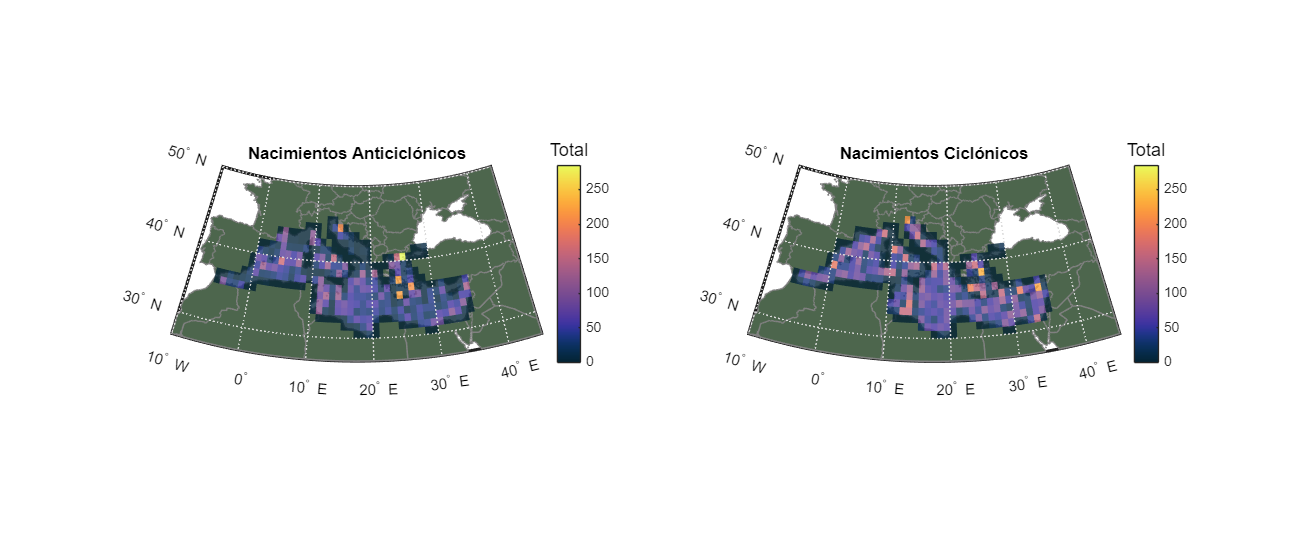


% Crea la figura
figure;
set(gcf, 'Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);

minC = min(min(nacimiento_celdasAN),min(nacimiento_celdasCIC));  % Encuentra el valor mínimo
maxC = max(max(nacimiento_celdasAN),max(nacimiento_celdasCIC));  % Encuentra el valor máximo
cmap =(cmocean('thermal'));  % Genera un mapa de colores con 80 colores

% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');

% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);
% Suponiendo que 'cells' contiene la información de las celdas (lon, lat)
% Tomamos los valores de lat y lon para la primera celda
for j = 1:length(cells)
    value = nacimiento_celdasAN(j);
    
    index = round((value - minC) / (maxC - minC) * (size(cmap, 1) - 1)) + 1;
    
    % Extrae el color correspondiente
    color = cmap(index, :);
    lon = cells(j).Longitude;
    lat = cells(j).Latitude;
    
    % Rellenar la celda con el color determinado
     h = fillm(lat, lon, 'FaceColor', color, 'EdgeColor', 'none');  % Dibuja la celda
    set(h, 'FaceAlpha', 0.8);  % Establece la opacidad a 0.8
    
end
% Título y etiquetas
title("Nacimientos Anticiclónicos");

% Mostrar la barra de colores
colormap(cmap);
clim([minC,maxC]);  
cb = colorbar; 

cb.Title.String=("Total");
cb.Title.FontSize = 12;


% Crea la figura ------------------
subplot(1, 2, 2);

cmap =(cmocean('thermal')); 
% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');

% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);
% Suponiendo que 'cells' contiene la información de las celdas (lon, lat)
% Tomamos los valores de lat y lon para la primera celda
for j = 1:length(cells)
    value = nacimiento_celdasCIC(j);
    
    index = round((value - minC) / (maxC - minC) * (size(cmap, 1) - 1)) + 1;
    
    % Extrae el color correspondiente
    color = cmap(index, :);
    lon = cells(j).Longitude;
    lat = cells(j).Latitude;
    
    % Rellenar la celda con el color determinado
     h = fillm(lat, lon, 'FaceColor', color, 'EdgeColor', 'none');  % Dibuja la celda
    set(h, 'FaceAlpha', 0.8);  % Establece la opacidad a 0.8    
end
% Título y etiquetas
title("Nacimientos Ciclónicos");

% Mostrar la barra de colores
colormap(cmap);
clim([minC,maxC]);  
cb = colorbar; 

cb.Title.String=("Total");
cb.Title.FontSize = 12;

## Muertes Por Celda y tipo 

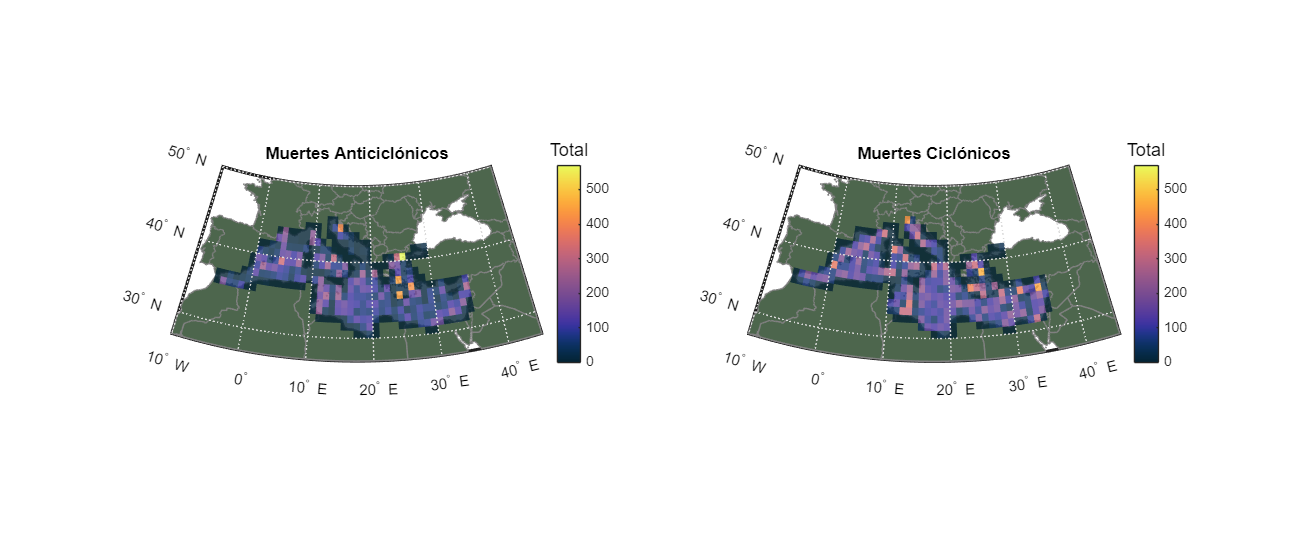

% Crea la figura
figure;
set(gcf, 'Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);

minC = min(min(muertes_celdasAN),min(muertes_celdasCIC));  % Encuentra el valor mínimo
maxC = max(max(muertes_celdasAN),max(muertes_celdasCIC));  % Encuentra el valor máximo
cmap =(cmocean('thermal'));  % Genera un mapa de colores con 80 colores

% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');

% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);
% Suponiendo que 'cells' contiene la información de las celdas (lon, lat)
% Tomamos los valores de lat y lon para la primera celda
for j = 1:length(cells)
    value = muertes_celdasAN(j);
    
    index = round((value - minC) / (maxC - minC) * (size(cmap, 1) - 1)) + 1;
    
    % Extrae el color correspondiente
    color = cmap(index, :);
    lon = cells(j).Longitude;
    lat = cells(j).Latitude;
    
    % Rellenar la celda con el color determinado
     h = fillm(lat, lon, 'FaceColor', color, 'EdgeColor', 'none');  % Dibuja la celda
    set(h, 'FaceAlpha', 0.8);  % Establece la opacidad a 0.8
    
end
% Título y etiquetas
title("Muertes Anticiclónicos");

% Mostrar la barra de colores
colormap(cmap);
clim([minC,maxC]);  
cb = colorbar; 

cb.Title.String=("Total");
cb.Title.FontSize = 12;


% Crea la figura ------------------
subplot(1, 2, 2);

cmap =(cmocean('thermal')); 
% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');

% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);
% Suponiendo que 'cells' contiene la información de las celdas (lon, lat)
% Tomamos los valores de lat y lon para la primera celda
for j = 1:length(cells)
    value = muertes_celdasCIC(j);
    
    index = round((value - minC) / (maxC - minC) * (size(cmap, 1) - 1)) + 1;
    
    % Extrae el color correspondiente
    color = cmap(index, :);
    lon = cells(j).Longitude;
    lat = cells(j).Latitude;
    
    % Rellenar la celda con el color determinado
     h = fillm(lat, lon, 'FaceColor', color, 'EdgeColor', 'none');  % Dibuja la celda
    set(h, 'FaceAlpha', 0.8);  % Establece la opacidad a 0.8    
end
% Título y etiquetas
title("Muertes Ciclónicos");

% Mostrar la barra de colores
colormap(cmap);
clim([minC,maxC]);  
cb = colorbar; 

cb.Title.String=("Total");
cb.Title.FontSize = 12;

## Vida Media Por Celda y tipo

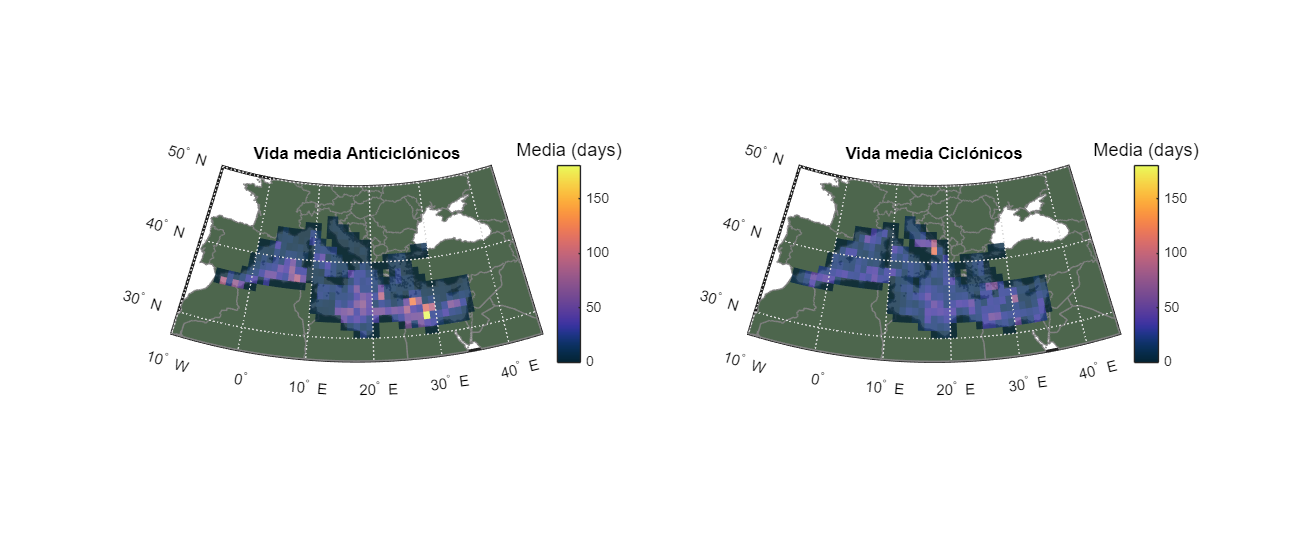

% Crea la figura
figure;
set(gcf, 'Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);

minC = min(min(vidamediaAN),min(vidamediaCIC));  % Encuentra el valor mínimo
maxC = max(max(vidamediaAN),max(vidamediaCIC));  % Encuentra el valor máximo
cmap =(cmocean('thermal'));  % Genera un mapa de colores con 80 colores

% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');

% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);
% Suponiendo que 'cells' contiene la información de las celdas (lon, lat)
% Tomamos los valores de lat y lon para la primera celda
for j = 1:length(cells)
    value = vidamediaAN(j);
    
    index = round((value - minC) / (maxC - minC) * (size(cmap, 1) - 1)) + 1;
    
    % Extrae el color correspondiente
    color = cmap(index, :);
    lon = cells(j).Longitude;
    lat = cells(j).Latitude;
    
    % Rellenar la celda con el color determinado
     h = fillm(lat, lon, 'FaceColor', color, 'EdgeColor', 'none');  % Dibuja la celda
    set(h, 'FaceAlpha', 0.8);  % Establece la opacidad a 0.8
    
end
% Título y etiquetas
title("Vida media Anticiclónicos");

% Mostrar la barra de colores
colormap(cmap);
clim([minC,maxC]);  
cb = colorbar; 

cb.Title.String=("Media (days)");
cb.Title.FontSize = 12;


% Crea la figura ------------------
subplot(1, 2, 2);

cmap =(cmocean('thermal')); 
% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');

% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);
% Suponiendo que 'cells' contiene la información de las celdas (lon, lat)
% Tomamos los valores de lat y lon para la primera celda
for j = 1:length(cells)
    value = vidamediaCIC(j);
    
    index = round((value - minC) / (maxC - minC) * (size(cmap, 1) - 1)) + 1;
    
    % Extrae el color correspondiente
    color = cmap(index, :);
    lon = cells(j).Longitude;
    lat = cells(j).Latitude;
    
    % Rellenar la celda con el color determinado
     h = fillm(lat, lon, 'FaceColor', color, 'EdgeColor', 'none');  % Dibuja la celda
    set(h, 'FaceAlpha', 0.8);  % Establece la opacidad a 0.8    
end
% Título y etiquetas
title("Vida media Ciclónicos");

% Mostrar la barra de colores
colormap(cmap);
clim([minC,maxC]);  
cb = colorbar; 

cb.Title.String=("Media (days)");
cb.Title.FontSize = 12;

## Ratio Nacimientos y muertes Ciclonicos/Anticiclonicos Por Celda

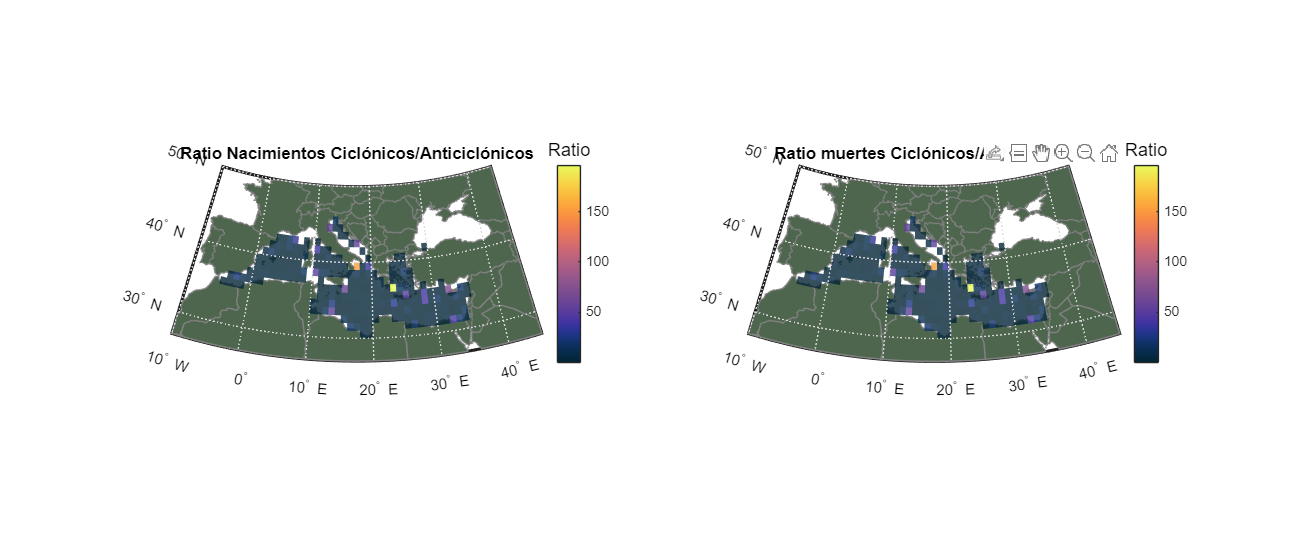

% Crea la figura
figure;
set(gcf, 'Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);

% Filtrar valores que no sean 0 ni Inf en ratio_nacimientos_celdas
valid_nacimientos = ratio_nacimientos_celdas(~isinf(ratio_nacimientos_celdas) & ratio_nacimientos_celdas ~= 0);
% Filtrar valores que no sean 0 ni Inf en ratio_muertes_celdas
valid_muertes = ratio_muertes_celdas(~isinf(ratio_muertes_celdas) & ratio_muertes_celdas ~= 0);
% Unir los valores válidos de ambas matrices
valores_validos = [valid_nacimientos(:); valid_muertes(:)]; % Convertir en vector columna

% Calcular el mínimo y máximo solo con valores válidos
minC = min(valores_validos);
maxC = max(valores_validos);
cmap =(cmocean('thermal'));  % Genera un mapa de colores con 80 colores

% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');

% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);
% Suponiendo que 'cells' contiene la información de las celdas (lon, lat)
% Tomamos los valores de lat y lon para la primera celda
for j = 1:length(cells)
    value = ratio_nacimientos_celdas(j);

    if ~isinf(value) && value ~= 0
    
        index = round((value - minC) / (maxC - minC) * (size(cmap, 1) - 1)) + 1;
        
        % Extrae el color correspondiente
        color = cmap(index, :);
        lon = cells(j).Longitude;
        lat = cells(j).Latitude;
        
        % Rellenar la celda con el color determinado
         h = fillm(lat, lon, 'FaceColor', color, 'EdgeColor', 'none');  % Dibuja la celda
        set(h, 'FaceAlpha', 0.8);  % Establece la opacidad a 0.8
    end
    
end
% Título y etiquetas
title("Ratio Nacimientos Ciclónicos/Anticiclónicos");

% Mostrar la barra de colores
colormap(cmap);
clim([minC,maxC]);  
cb = colorbar; 

cb.Title.String=("Ratio");
cb.Title.FontSize = 12;


% Crea la figura ------------------
subplot(1, 2, 2);

cmap =(cmocean('thermal')); 
% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');

% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);
% Suponiendo que 'cells' contiene la información de las celdas (lon, lat)
% Tomamos los valores de lat y lon para la primera celda
for j = 1:length(cells)
    value = ratio_muertes_celdas(j);
    if ~isinf(value) && value ~= 0
    
        index = round((value - minC) / (maxC - minC) * (size(cmap, 1) - 1)) + 1;
        
        % Extrae el color correspondiente
        color = cmap(index, :);
        lon = cells(j).Longitude;
        lat = cells(j).Latitude;
        
        % Rellenar la celda con el color determinado
         h = fillm(lat, lon, 'FaceColor', color, 'EdgeColor', 'none');  % Dibuja la celda
        set(h, 'FaceAlpha', 0.8);  % Establece la opacidad a 0.8 
    end
end
% Título y etiquetas
title("Ratio muertes Ciclónicos/Anticiclónicos");

% Mostrar la barra de colores
colormap(cmap);
clim([minC,maxC]);  
cb = colorbar; 
cb.Title.String=("Ratio");
cb.Title.FontSize = 12;

# Representación sin CELDAS

#### Clasificación Data

trackAN = unique(Data_ANC.track); trackCIC = unique(Data_CIC.track);

trayectoriasCIC={}; trayectoriasAN={};
% Inicializar un vector para almacenar las longitudes mínimas para cada track
NacimLon_AN = NaN(length(trackAN), 1); NacimLat_AN = NaN(length(trackAN), 1);
NacimLon_CIC = NaN(length(trackCIC ), 1); NacimLat_CIC = NaN(length(trackCIC ), 1);

MuertLon_AN = NaN(length(trackAN), 1); MuertLat_AN = NaN(length(trackAN), 1);
MuertLon_CIC = NaN(length(trackCIC ), 1); MuertLat_CIC = NaN(length(trackCIC), 1);

%REPRESENTA SOLO EVENTOS QUE DUREN MAS QUE, EN SEMANAS
LifetimeMinimo=0;

% Recorrer cada uno de los valores únicos de trackAN
for i = 1:length(trackAN)
    % Filtrar las filas de Data_ANC donde track es igual al valor actual de trackAN
    idxTrack = Data_ANC.track == trackAN(i);
    
    % Obtener las longitudes asociadas a ese track
    longitudesTrack = Data_ANC.longitude(idxTrack);
    latitudesTrack = Data_ANC.latitude(idxTrack);
   
    VidaANC=Data_ANC.lifetime(idxTrack);
    
    if max(VidaANC)/7 >= LifetimeMinimo
        trayectoriasAN{i} = [latitudesTrack, longitudesTrack]; 
        % Obtener el valor mínimo de longitud para ese track
        NacimLon_AN(i) = longitudesTrack(1);
        NacimLat_AN(i) = latitudesTrack(1);
        
        MuertLon_AN(i) = longitudesTrack(end);
        MuertLat_AN(i) = latitudesTrack(end);

    end
end

% Recorrer cada uno de los valores únicos de trackCIC
for i = 1:length(trackCIC)
    % Filtrar las filas de Data_ANC donde track es igual al valor actual de trackAN
    idxTrackC = Data_CIC.track == trackCIC(i);
    
    % Obtener las longitudes asociadas a ese track
    longitudesTrackC = Data_CIC.longitude(idxTrackC);
    latitudesTrackC = Data_CIC.latitude(idxTrackC);

    VidaCIC=Data_CIC.lifetime(idxTrackC);

    if max(VidaCIC)/7 >= LifetimeMinimo
        trayectoriasCIC{i} = [latitudesTrackC, longitudesTrackC]; 
        % Obtener el valor mínimo de longitud para ese track
        NacimLon_CIC(i) = longitudesTrackC(1);
        NacimLat_CIC(i) = latitudesTrackC(1);
        
        MuertLon_CIC(i) = longitudesTrackC(end);
        MuertLat_CIC(i) = latitudesTrackC(end);

    end
end

num_trayectoriasCIC=length(trayectoriasCIC);
num_trayectoriasANC=length(trayectoriasAN);

#### Representación Nacimientos por tipo

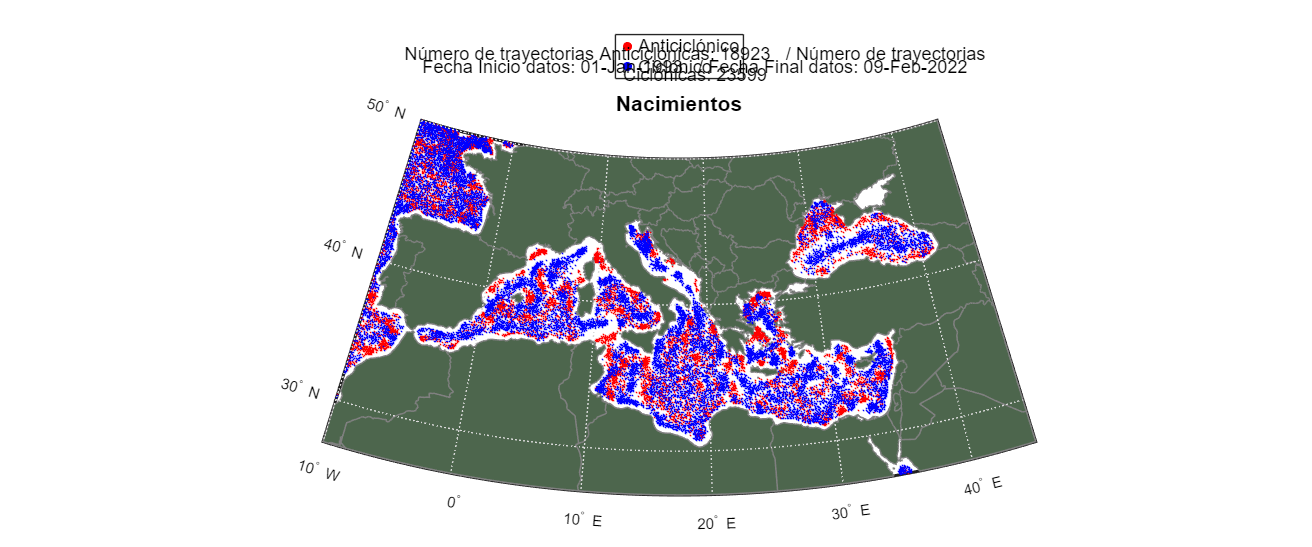

figure;

set(gcf, 'Position', [100, 100, 1200, 500]);

% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');

% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);

geoshow(NacimLat_AN, NacimLon_AN,"DisplayType","point","Marker",".","MarkerSize",0.1,"Color","red");
geoshow(NacimLat_CIC, NacimLon_CIC,"DisplayType","point","Marker",".","MarkerSize",0.1,"Color","blue");




% Crear un objeto gráfico vacío para la leyenda del color anticiclónico (rojo)
h_legend_ciclonico = plot(NaN, NaN, 'o', 'MarkerFaceColor', "blue", 'MarkerEdgeColor', 'none');
% Crear un objeto gráfico vacío para la leyenda del color ciclónico (azul)
h_legend_anticiclonico  = plot(NaN, NaN, 'o', 'MarkerFaceColor', "red", 'MarkerEdgeColor', 'none');
% Añadir la leyenda manualmente
legend([h_legend_anticiclonico, h_legend_ciclonico], ...
{'Anticiclónico', 'Ciclónico'}, ...
'Location', 'northoutside', 'FontSize', 12);

title("Nacimientos", 'FontSize', 14)
xlabel("Longitud")
ylabel("Latitud")

textoF = ['Fecha Inicio datos: ',datestr(FechaInicioDATOS), ...
         '   / Fecha Final datos: ', datestr(FechaFinalDATOS)];
% Usar annotation para colocar el texto fuera de los ejes
annotation('textbox', [0.28, 0.845, 0.5, 0], 'String', textoF, ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 12, 'EdgeColor', 'none');

% Concatenar las dos cadenas de texto en una sola
texto = ['Número de trayectorias Anticiclónicas: ', num2str(num_trayectoriasANC), ...
         '   / Número de trayectorias Ciclónicas: ', num2str(num_trayectoriasCIC)];
% Usar annotation para colocar el texto combinado
annotation('textbox', [0.28, 0.83, 0.5, 0], 'String',texto, ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 12, 'EdgeColor', 'none');

#### Representación Muertes por tipo

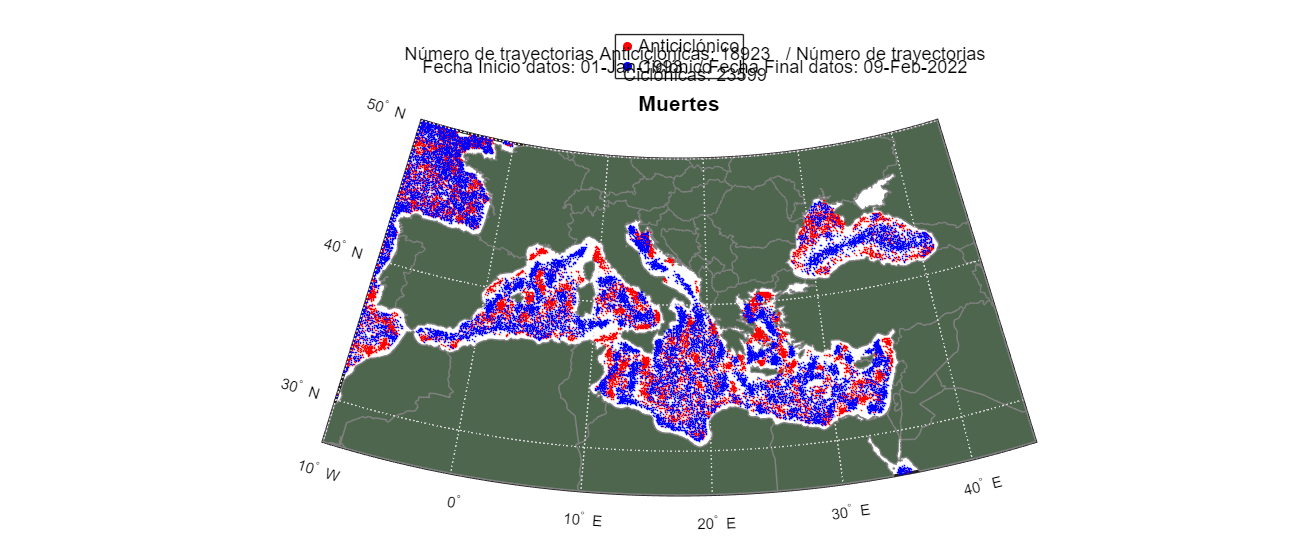

figure;

set(gcf, 'Position', [100, 100, 1200, 500]);

% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');

% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);

geoshow(MuertLat_AN, MuertLon_AN,"DisplayType","point","Marker",".","MarkerSize",0.1,"Color","red");
geoshow(MuertLat_CIC, MuertLon_CIC,"DisplayType","point","Marker",".","MarkerSize",0.1,"Color","blue");

% Crear un objeto gráfico vacío para la leyenda del color anticiclónico (rojo)
h_legend_ciclonico = plot(NaN, NaN, 'o', 'MarkerFaceColor', "blue", 'MarkerEdgeColor', 'none');
% Crear un objeto gráfico vacío para la leyenda del color ciclónico (azul)
h_legend_anticiclonico  = plot(NaN, NaN, 'o', 'MarkerFaceColor', "red", 'MarkerEdgeColor', 'none');
% Añadir la leyenda manualmente
legend([h_legend_anticiclonico, h_legend_ciclonico], ...
{'Anticiclónico', 'Ciclónico'}, ...
'Location', 'northoutside', 'FontSize', 12);

grid on
title("Muertes",'FontSize', 14)
xlabel("Longitud")
ylabel("Latitud")

textoF = ['Fecha Inicio datos: ',datestr(FechaInicioDATOS), ...
         '   / Fecha Final datos: ', datestr(FechaFinalDATOS)];
% Usar annotation para colocar el texto fuera de los ejes
annotation('textbox', [0.28, 0.845, 0.5, 0], 'String', textoF, ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 12, 'EdgeColor', 'none');

% Concatenar las dos cadenas de texto en una sola
texto = ['Número de trayectorias Anticiclónicas: ', num2str(num_trayectoriasANC), ...
         '   / Número de trayectorias Ciclónicas: ', num2str(num_trayectoriasCIC)];
% Usar annotation para colocar el texto combinado
annotation('textbox', [0.28, 0.83, 0.5, 0], 'String',texto, ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 12, 'EdgeColor', 'none');

#### Representación Conjunta Muertes y Nacimientos

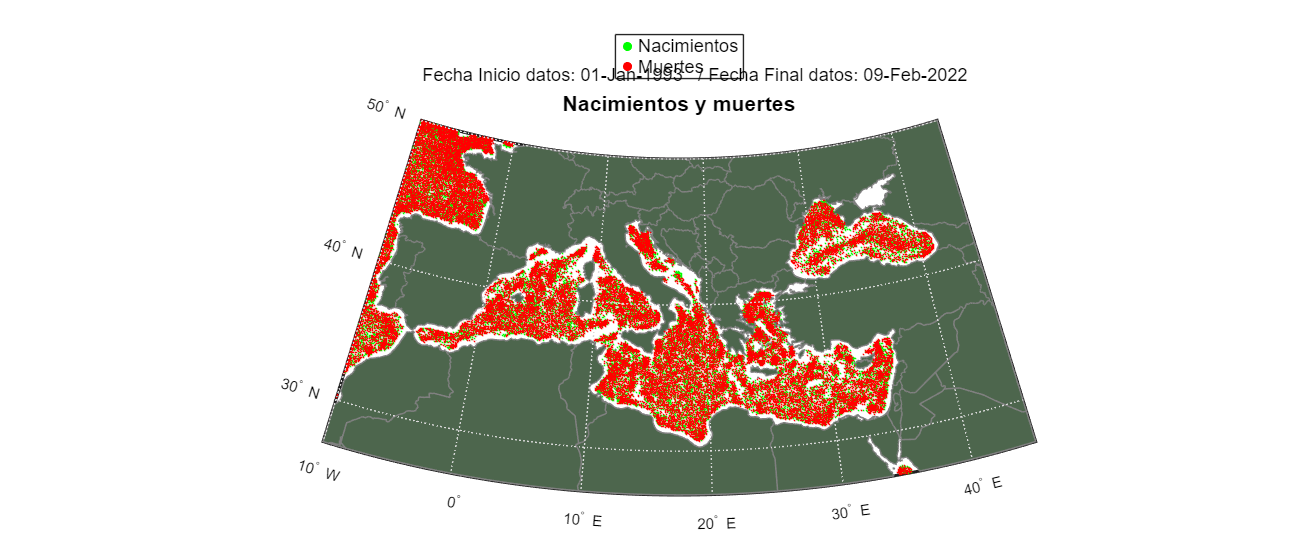

figure;

set(gcf, 'Position', [100, 100, 1200, 500]);

% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');

% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);

tamanoPuntos=0.3;
geoshow(NacimLat_AN, NacimLon_AN,"DisplayType","point","Marker",".","MarkerSize",tamanoPuntos,"Color",	'green');
geoshow(NacimLat_CIC, NacimLon_CIC,"DisplayType","point","Marker",".","MarkerSize",tamanoPuntos,"Color",'green');

geoshow(MuertLat_AN, MuertLon_AN,"DisplayType","point","Marker",".","MarkerSize",tamanoPuntos,"Color",'red');
geoshow(MuertLat_CIC, MuertLon_CIC,"DisplayType","point","Marker",".","MarkerSize",tamanoPuntos,"Color",'red');


% Crear un objeto gráfico vacío para la leyenda del color anticiclónico (rojo)
h_legend_nacimientos = plot(NaN, NaN, 'o', 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'none');
% Crear un objeto gráfico vacío para la leyenda del color ciclónico (azul)
h_legend_muertes = plot(NaN, NaN, 'o', 'MarkerFaceColor', "red", 'MarkerEdgeColor', 'none');
% Añadir la leyenda manualmente
legend([h_legend_nacimientos, h_legend_muertes], ...
{'Nacimientos', 'Muertes'}, ...
'Location', 'northoutside', 'FontSize', 12);



title("Nacimientos y muertes",'FontSize', 14)
textoF = ['Fecha Inicio datos: ',datestr(FechaInicioDATOS), ...
         '   / Fecha Final datos: ', datestr(FechaFinalDATOS)];
% Usar annotation para colocar el texto fuera de los ejes
annotation('textbox', [0.28, 0.83, 0.5, 0], 'String', textoF, ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 12, 'EdgeColor', 'none');

#### Trayectorias por tipo

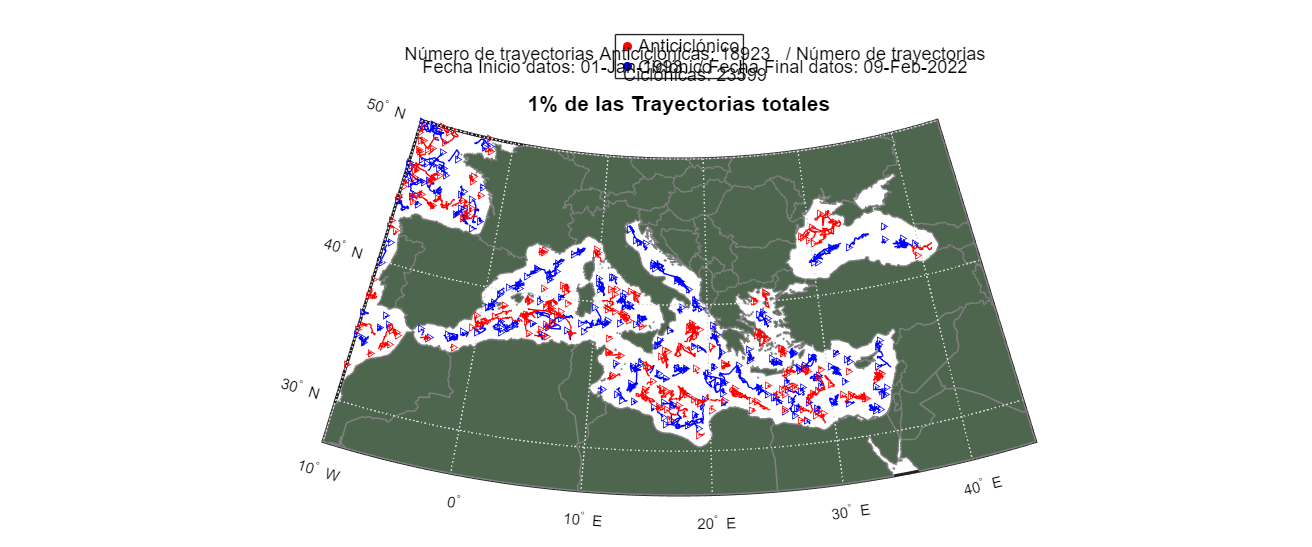


figure;
set(gcf, 'Position', [100, 100, 1200, 500]);

% Crear el mapa global usando worldmap
ax = worldmap([lat_min_bound lat_max_bound], [long_min_bound long_max_bound]);
setm(ax, 'Frame', 'on', 'Grid', 'on', 'ParallelLabel', 'on', 'MeridianLabel', 'on');
% Mostrar los límites de los países
geoshow(countries, 'FaceColor', [0.3 0.4 0.3], 'EdgeColor', [0.5 0.5 0.5], 'LineWidth', 1);


% Recorrer todas las trayectorias almacenadas en la celda
for i = 1:num_trayectoriasCIC/100
    datos = trayectoriasCIC{i}; % Extraer la matriz de la celda
    if isempty(datos)
        continue; % Saltar esta iteración si la celda está vacía
    end
    latitudes = datos(:,1);
    longitudes = datos(:,2);% Segunda columna: longitudes
    
    % Dibujar la trayectoria con geoshow
    geoshow(latitudes, longitudes, 'DisplayType', 'line', 'Color', 'blue', 'LineWidth', 0.1);
    geoshow(latitudes(end), longitudes(end), 'DisplayType','point','Marker','>','MarkerSize',4,'Color', 'blue');
end

for i = 1:num_trayectoriasANC/100
    datos = trayectoriasAN{i}; % Extraer la matriz de la celda
    if isempty(datos)
        continue; % Saltar esta iteración si la celda está vacía
    end
    latitudes = datos(:,1);
    longitudes = datos(:,2);% Segunda columna: longitudes
    
    % Dibujar la trayectoria con geoshow
    geoshow(latitudes, longitudes, 'DisplayType','line','LineWidth', 0.1,'Color', 'r');
    geoshow(latitudes(end), longitudes(end), 'DisplayType','point','Marker','>','MarkerSize',4,'Color', 'r');

   
end

% Crear un objeto gráfico vacío para la leyenda del color anticiclónico (rojo)
h_legend_ciclonico = plot(NaN, NaN, 'o', 'MarkerFaceColor', "blue", 'MarkerEdgeColor', 'none');
% Crear un objeto gráfico vacío para la leyenda del color ciclónico (azul)
h_legend_anticiclonico  = plot(NaN, NaN, 'o', 'MarkerFaceColor', "red", 'MarkerEdgeColor', 'none');
% Añadir la leyenda manualmente
legend([h_legend_anticiclonico, h_legend_ciclonico], ...
{'Anticiclónico', 'Ciclónico'}, ...
'Location', 'northoutside', 'FontSize', 12);

title("1% de las Trayectorias totales",'FontSize', 14)
% Concatenar las dos cadenas de texto en una sola
textoF = ['Fecha Inicio datos: ',datestr(FechaInicioDATOS), ...
         '   / Fecha Final datos: ', datestr(FechaFinalDATOS)];
% Usar annotation para colocar el texto fuera de los ejes
annotation('textbox', [0.28, 0.845, 0.5, 0], 'String', textoF, ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 12, 'EdgeColor', 'none');

% Concatenar las dos cadenas de texto en una sola
texto = ['Número de trayectorias Anticiclónicas: ', num2str(num_trayectoriasANC), ...
         '   / Número de trayectorias Ciclónicas: ', num2str(num_trayectoriasCIC)];
% Usar annotation para colocar el texto combinado
annotation('textbox', [0.28, 0.83, 0.5, 0], 'String',texto, ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 12, 'EdgeColor', 'none');